**ecoSUB_process**

Script to process and plot science and engineerig data from ecoSUB instruments. 

Requires:

-     gsw toolbox [http://www.teos-10.org/software.htm](http://www.teos-10.org/software.htm)

-     cmocean [https://uk.mathworks.com/matlabcentral/fileexchange/57773-cmocean-perceptually-uniform-colormaps](https://uk.mathworks.com/matlabcentral/fileexchange/57773-cmocean-perceptually-uniform-colormaps)

-     m_map [https://www.eoas.ubc.ca/~rich/map.html](https://www.eoas.ubc.ca/~rich/map.html) 

*Lewis Drysdale, 2021, lewis.drysdale@sams.ac.uk*

clearvars; close('all')

Set filepaths and strings for incoming and outgoing data

- Set paths to data and figure folder

- Change testdate variable to reflect the folder in /logs

- Check the IMEI number to match the vehicle used

- Choose  quality control parameters to apply to the data

% 1. set paths to data and figure folder
indir       ='C:\ecoSUB C3 GUI\Logs';           % set file path 
figdir      = '\Users\SA01LD\Desktop\ecoSUB-toolbox\figures\'; % set outpath for figures
% 2. change testdate
testdate    ='20210811';                        % enter test date

% 3. check IMEI
imei        ='300434062118160' ;                % unique to each instrument

infolder    =fullfile(indir,testdate,imei);     % build file path
state_file  = dir([infolder filesep '*_ecosub_state_v2.csv']); % list relevant files
cstate_file = dir([infolder filesep '*_current_state.csv']); % list relevant files

% 4. choose some quality control parameters
lat_lim     = [56.45 56.5];  % geographical exclusion
lon_lim     = [-5.5 -5.4];  % geographical exclusion
dep_lim     = 0.2;          % depth exclusion

for kk = 1:numel(state_file)
    % read state v2
    statev2=readtable([infolder filesep state_file(kk).name],"PreserveVariableNames",false);
    % read current state
    cstate=readtable([infolder filesep cstate_file(kk).name],"PreserveVariableNames",false);

Extract data, apply QA to science data, and conversion to TEOS-10    

    % apply quality control filters
    q1      = statev2.Depth<=dep_lim;
    q2      =statev2.Latitude>=lat_lim(2) | statev2.Latitude<=lat_lim(1);
    q3      =statev2.Longitude>=lon_lim(2) | statev2.Longitude<=lon_lim(1);
    ix      = q1 | q2 | q3;
    
    statev2.D       =statev2.Depth;    
    statev2.C       =statev2.Conductivity;
    statev2.T       =statev2.Temperature;
    statev2.Lat     =statev2.Latitude;
    statev2.Lon     =statev2.Longitude;
    
    statev2.D(ix)=NaN;
    statev2.C(ix)=NaN;
    statev2.T(ix)=NaN;
    statev2.Lat(ix)=NaN;
    statev2.Lon(ix)=NaN;
    
    % calculate salinity and TEOS-10 salinity, temperature, density
    statev2.SP              = gsw_SP_from_C(statev2.C,statev2.T,statev2.D);
    [statev2.SA, in_ocean]  = gsw_SA_from_SP(statev2.SP,statev2.D,statev2.Lon,statev2.Lat);
    statev2.CT              = gsw_CT_from_t(statev2.SA,statev2.T,statev2.D);
    statev2.rho             = gsw_rho(statev2.SA,statev2.CT,statev2.D);

    % extract engineering units
    Time    =statev2.Time;
    mtime   =datenum(datetime(Time, 'convertfrom','posixtime'));
    Speed   =statev2.ForwardSpeed;
    Heading =statev2.Heading;
    Pitch   =statev2.Pitch;
    Roll    =statev2.Roll;
    RPM     =statev2.RPM;
    B1volt  =statev2.Battery1Volt;
    B1crnt  =statev2.Battery1Current;
    Rangle  =statev2.RudderAngle;
    
    % get mission name and filepath 
    mission =char(statev2.MissionName(1));
    fpath=fullfile(figdir,[char(statev2.MissionName(1)) '-' datestr(mtime(1),30)]);


Plot science data

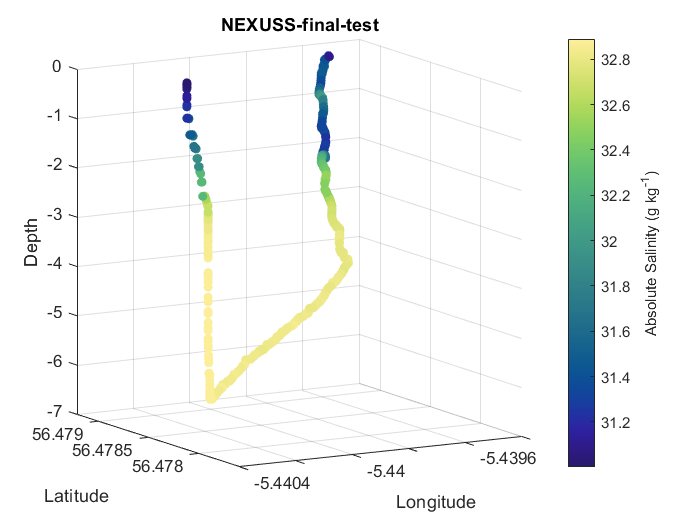

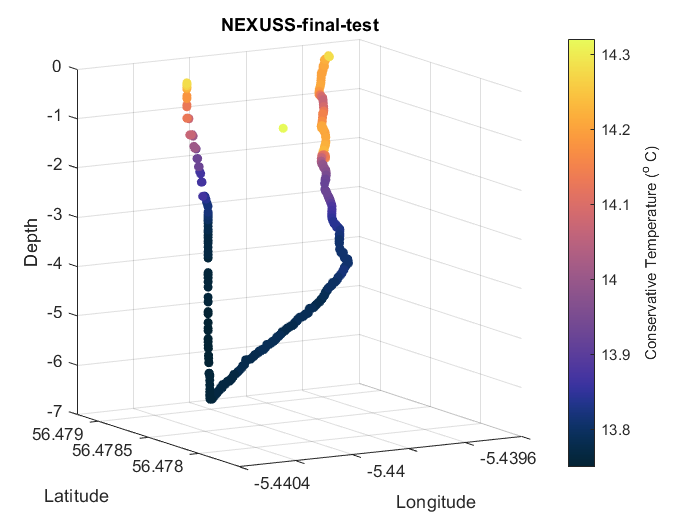

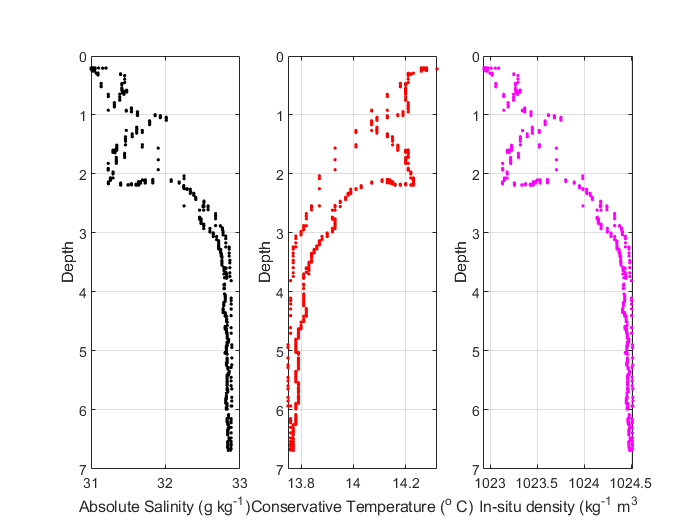

    
    if sum(~isnan(statev2.SP))>0
            ecoSUB_scatter(statev2.Lon,statev2.Lat,statev2.D,statev2.SA,fpath,'Absolute Salinity',mission);
            ecoSUB_scatter(statev2.Lon,statev2.Lat,statev2.D,statev2.T,fpath,'Conservative Temperature',mission);
            ecoSUB_profile(statev2,fpath,'all')
    end

Plot vehicle engineering units

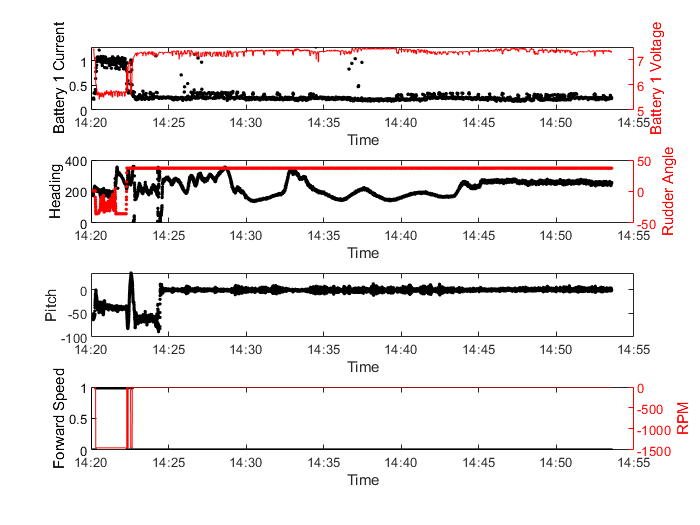

ecoSUB_plot_engineering

fname=fullfile(figdir,[char(statev2.MissionName(1)) '-' datestr(mtime(1),30) '-track']);
bathy='ardmucknish_bay'

bathy = 'ardmucknish_bay'

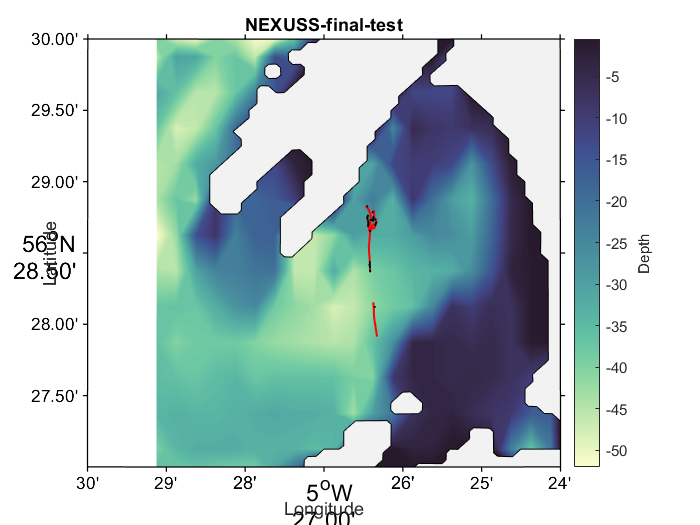

ecoSUB_track(statev2,lat_lim,lon_lim,bathy,fname)

end